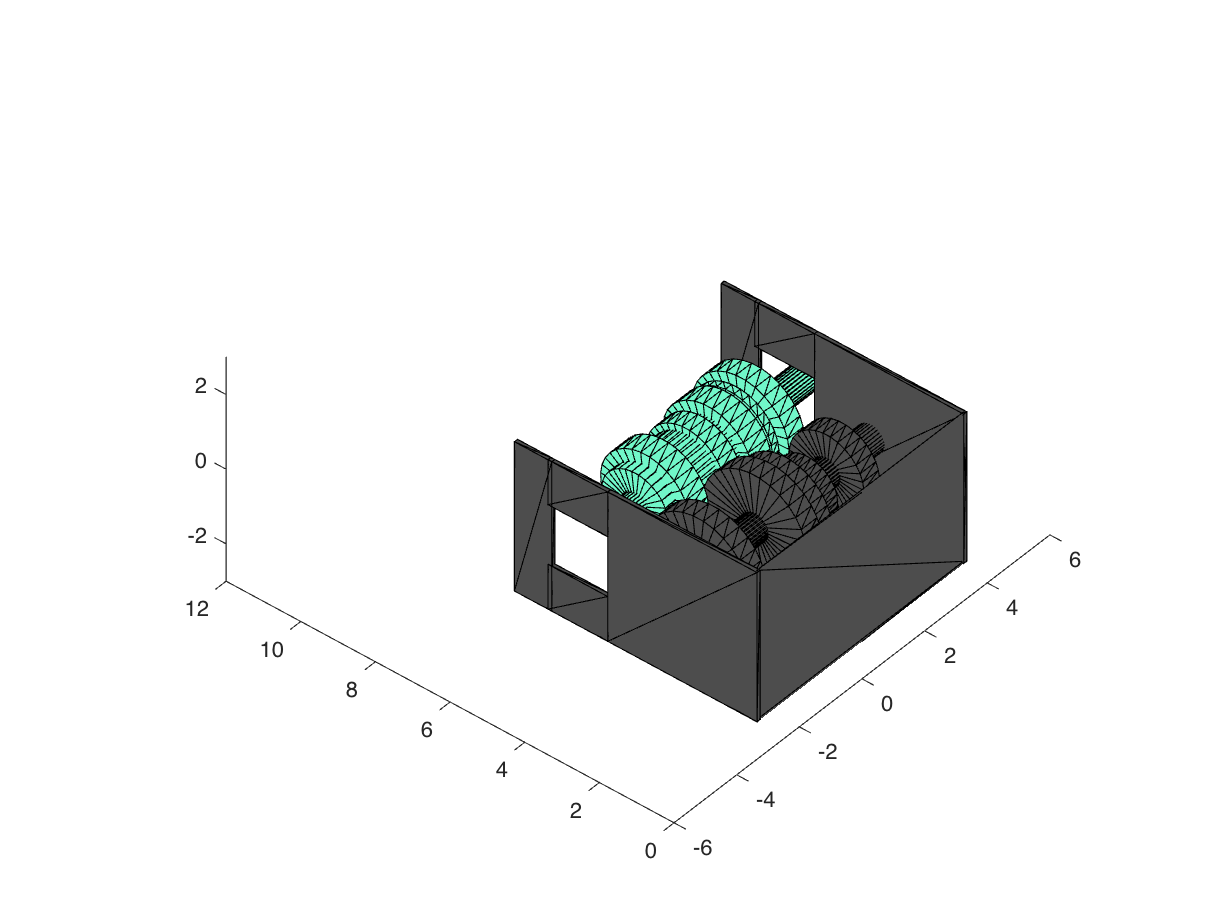

clf;
clear all;
close all;

%Start Pos
startx = 1.2; starty = 4.8; startz = 0; startqx = 0; startqy = 0; startqz = 0; startqw = 1;
%End Pos
endx = -2; endy = 8; endz = 1; endqx = 0; endqy = 0; endqz = 0; endqw = 1;

engine= MakeEngine(6.6,6.5);
shaft = MakeShaft;
addShaft(engine,shaft,trvec2tform([startx starty startz]));
show(engine,gca)
axis equal

xlim([-6 6])
ylim([0 12])
zlim([-3 3])
view([-50 40])

c_space_bounds = [[-5 5]; [0 10];[-5 5]; [-pi/2 pi/2];[-pi/2 pi/2];[-pi/2 pi/2];[-pi/2 pi/2]];

ss = stateSpaceSE3(c_space_bounds);
ss.WeightQuaternion = 2;

## Create a Custom State Validator

The planner requires a customized state validator to enable collision checking between furniture and the fixtures in the room. The provided class, `ExampleHelperFurnitureInRoomValidator`, checks the validity of the furniture states based on the pairwise convex polygon collision checking functions. The class automatically creates a engineand puts the weird-shaped furniture in it at construction.

% Set the initial pose of the furniture
initPose = trvec2tform([startx starty startz]);

% Create a customized state validator
sv = OccupancyMapCreator(ss, initPose);

% Reduce the validation distance
% Validation distance determines the granularity of interpolation when
% checking the motion that connects two states.
sv.ValidationDistance = 0.1;

## Configure the Path Planner

Use `plannerRRTStar` as the planner and specify the custom state space and state validator. Specify additional parameters for the planner. The `GoalReached` example helper function returns `true` when a feasible path gets close enough to the goal within a threshold. This exits the planner.

% Create the planner
rrt = plannerRRTStar(ss, sv);

% Set ball radius for searching near neighbors
rrt.BallRadiusConstant = 1000;

% Exit as soon as a path is found
rrt.ContinueAfterGoalReached = true;

% The motion length between two furniture poses should be less than 0.4 m
rrt.MaxConnectionDistance = 0.4;

% Increase the max iterations
rrt.MaxIterations = 1000;

% Use a customized goal function 
rrt.GoalReachedFcn = @isGoal;

## Plan the Move

Set a start and end pose for the furniture. This example moves from one pole to the other and rotates the chair `pi` radians. Plan the path between poses. Visualize the search tree and final path.

% Set the init and goal poses
start = [startx starty startz startqw startqx startqy startqz];
goal = [endx endy endz endqw endqx endqy endqz];

% Set random number seed for repeatability
rng(0, 'twister');
[path, solnInfo] = plan(rrt,start,goal);

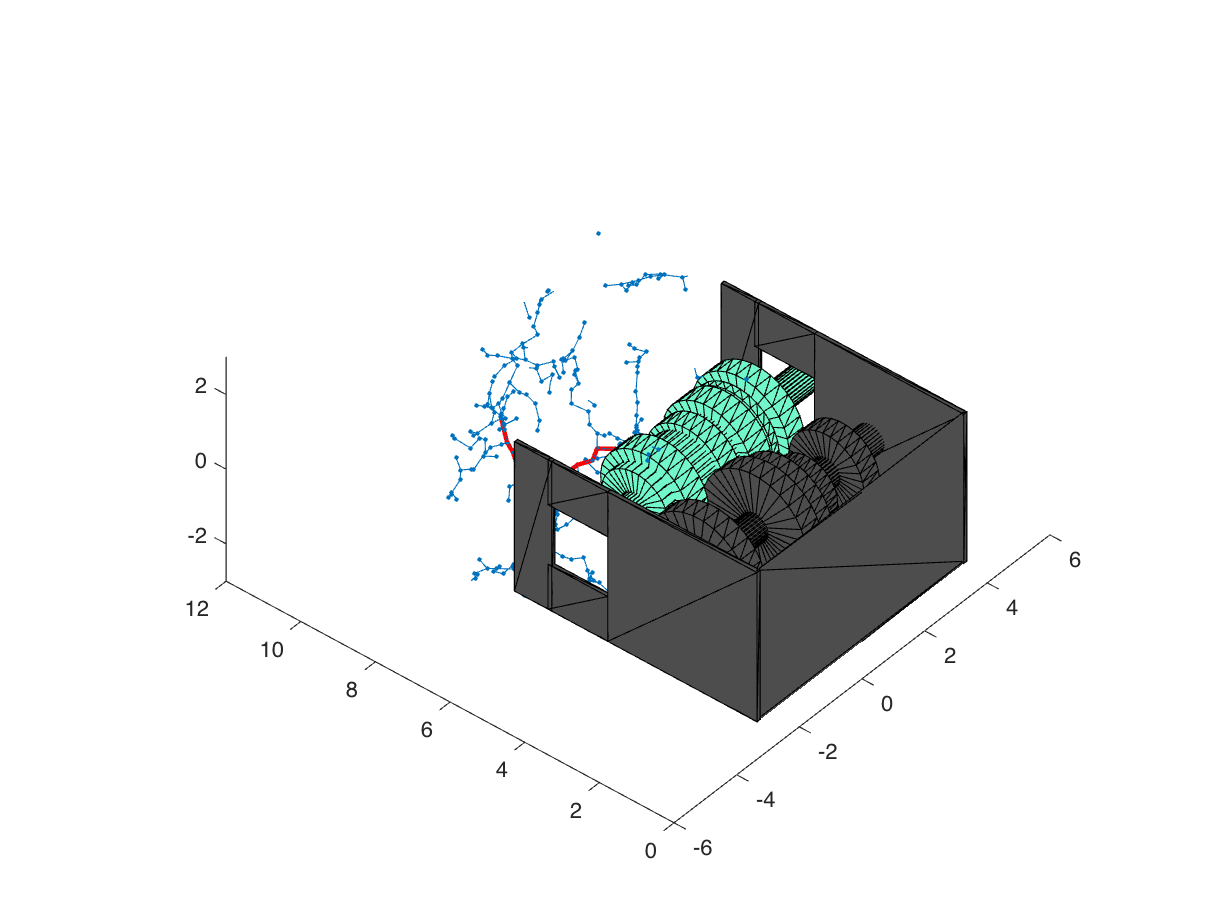


hold on% Search tree
plot3(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2),solnInfo.TreeData(:,3) , '.-');
% Interpolate path and plot points
interpolate(path,200)
plot3(path.States(:,1), path.States(:,2),path.States(:,3), 'r-', 'LineWidth', 2)
hold off

## Visualize the Motion

An example helper is provided for smoothing the path by cutting corners of the path where possible. Animate the motion of the furniture from start to goal pose. The animation plot shows intermediate states as the furniture navigates to the goal position.

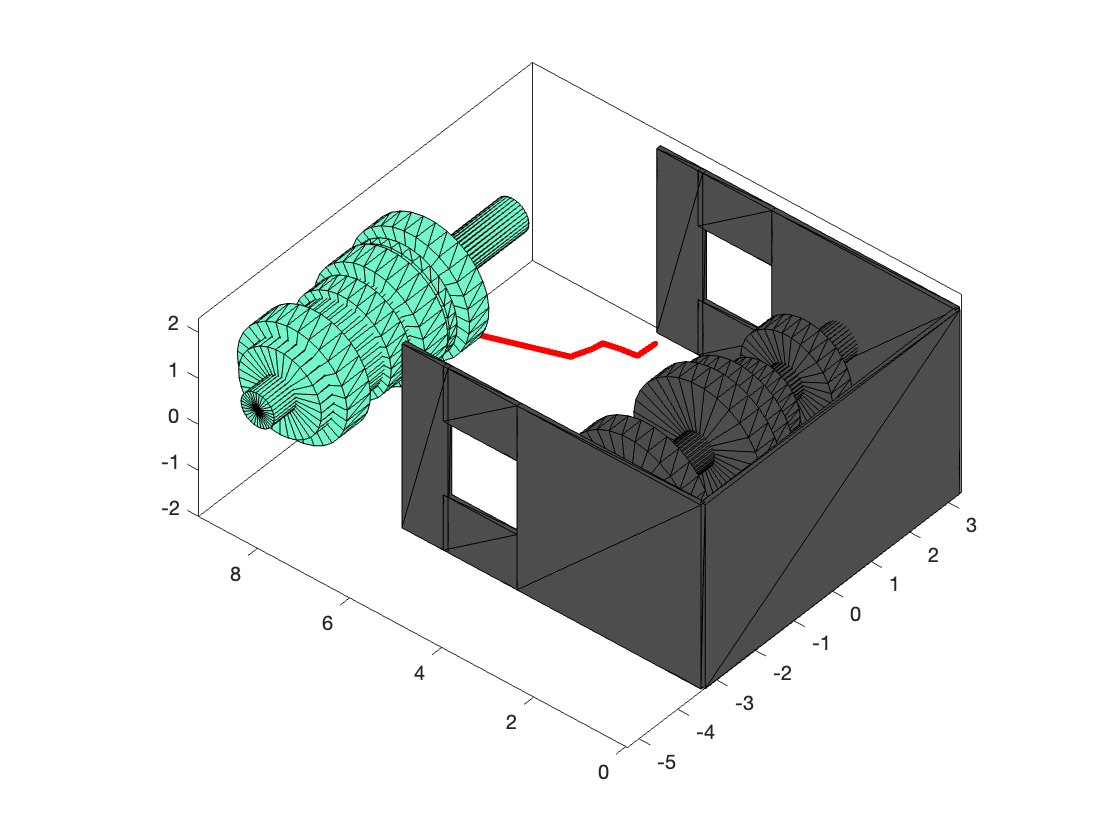


% Smooth the path, cut the corners wherever possible
pathSm = pathSmoother(path, sv);
interpolate(pathSm,200);

f = figure;
animateFurnitureMotion(sv.Engine,1,pathSm.States, axes(f));